[filepath,name,ext] = fileparts(which('example_simple'));
filepath_model = strjoin({filepath,'simple.inp'},'\');
mdl = swmm(filepath_model);


% create a copy of the model to enable editing
dir_model_copy = '\models\test\';
mdl = mdl.new_copy(dir_model_copy, 'overwrite',true);
mdl.read_inp2

ans =   swmm with properties:

           dir_main: '\models\test'
        dir_results: []
           dir_data: []
          dir_debug: []
    dir_data_parent: []
             locked: 0
               name: 'simple_editing_editing_editing_editing_editing_editing_editing_editing_editing_editing_editing_editing_editing_editing'
          debug_log: {}
                inp: '\models\test\simple_editing_editing_editing_editing_editing_editing_editing_editing_editing_editing_editing_editing_editing_editing.inp'
                rpt: '\models\test\simple_editing_editing_editing_editing_editing_editing_editing_editing_editing_editing_editing_editing_editing_editing.rpt'
         class_info: [21×6 table]
                  p: [1×1 struct]
             shapes: []


% view SWMM class data
disp(struct2table(mdl.p.subcatchments))

     Name     RainGage    Outlet    Area    PercentImperv    Width    PercentSlope    CurbLen     Snowpack 
    ______    ________    ______    ____    _____________    _____    ____________    _______    __________

    {'S1'}    {'rg_1'}    {'J1'}     4           50           400         0.5            0       {0×0 char}
    {'S2'}    {'rg_1'}    {'J2'}     4           10           400         0.5            0       {0×0 char}
    {'S3'}    {'rg_1'}    {'J3'}     4           90           400         0.5            0       {0×0 char}



disp(struct2table(mdl.p.conduits))

     Name     FromNode     ToNode     Length    Roughness    InOffset    OutOffset    InitFlow    MaxFlow
    ______    ________    ________    ______    _________    ________    _________    ________    _______

    {'C3'}     {'J3'}     {'J4'  }     400        0.01          0            0           0           0   
    {'C4'}     {'J4'}     {'OUT1'}     400        0.01          0            0           0           0   
    {'C2'}     {'J2'}     {'J4'  }     400        0.01          0            0           0           0   
    {'C1'}     {'J1'}     {'J2'  }     400        0.01          0            0           0           0   



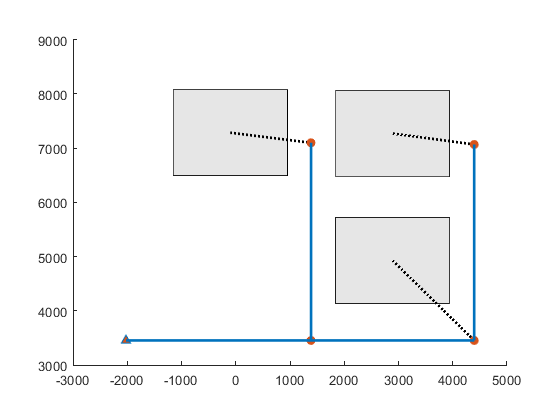

% draw the model elements on a map
figure('Name','model_layout')
mdl = mdl.draw;

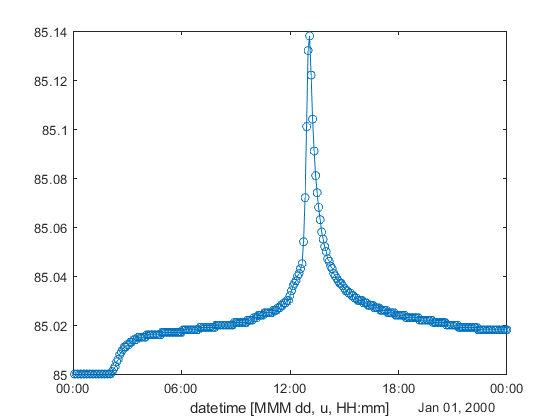

% run simulation for the model copy
mdl.runsim;
tt_outfl = mdl.results_tt('OUT1');
figure('Name','outflow_hydrograph');
plot_tt(tt_outfl,'o-');

% randomly sample n new 'Area' values for all subcatchments in model
n = 100;
param = 'PercentImperv';
x = 50 + 50 * randn(numel(mdl.p.subcatchments),n);
lim_upper = 100;
lim_lower = 0;
x(x>lim_upper) = lim_upper;
x(x<lim_lower) = lim_lower;

% plot the sample distributions
fh = figure('Name','sample_distributions')

fh =   Figure (50: sample_distributions) with properties:

      Number: 50
        Name: 'sample_distributions'
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


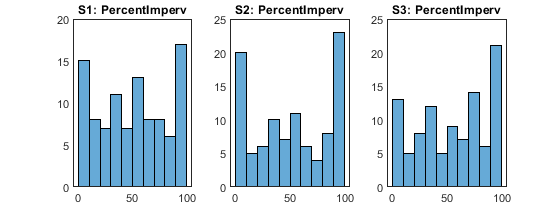

fh.Position(3:4) = fh.Position(3:4) .* [1, 0.5];
for i2 = 1:numel(mdl.p.subcatchments)
    subplot(1,numel(mdl.p.subcatchments),i2)
    histogram(x(i2,:),'numbins',10)
    title([mdl.p.subcatchments(i2).Name,': ', param]);
end


% evaluate each model
tt_aggr = timetable(tt_outfl.Properties.RowTimes);
for i2 = 1:n
    mdl.subcatchments(:,param).Variables = (x(:,i2));
    mdl.write_inp;
    mdl.runsim;
    tt_outfl = mdl.results_tt('OUT1');
    tt_aggr(:,['n',num2str(i2)]) = tt_outfl(:,'inflow');
end

Unrecognized method, property, or field 'subcatchments' for class 'swmm'.


% plot the outflow hydrographs
figure('Name','outflow_hydrograph_MC');
[ah,~] = plot_ue(tt_aggr);
ah.XLim = [mdl.options.START_DATE + hours(12), mdl.options.END_DATE - hours(10)]; % truncate x-limits to focus on peak